# **Quick Model and Eigen Visualization**

This live script is written as a guided walkthrough for a post-processing workflow. It focuses on retrieving, organizing, and visualizing model or response data after an OpenSees analysis. Read the text cells first, then run each code cell in order so that the variables, model state, and recorded results are available for the later sections.

At any point during model creation, you can run the ``ops.vis.plotModel()`` or ``ops.vis.plotEigen()`` to visualize the current model’s geometric details and eigen modes.

### Model visualization

This section creates the finite-element idealization used by the rest of the example. Check the dimensions, tags, and connectivity here before moving on.

clc; clear; close all;

First, instantiate the OpenSeesMatlab interface class. This class provides native OpenSees commands, as well as additional visualization, pre/post-processing, and utility methods.

opsMAT = OpenSeesMatlab();
ops = opsMAT.opensees;

For example, the `tool` property provides a function `loadExamples` to run some built-in models. Of course, you can run your own model; the built-in model is used here for demonstration purposes only.

ops.wipe();
opsMAT.utils.loadExamples("ArchBridge2");
% or your model here

We can visualize the model using the `plotModel` function in the `vis` attribute.

[OpenSeesMatlab] Model summary
  Nodes: 241
  Beam elements: 367
  Shell elements: 72


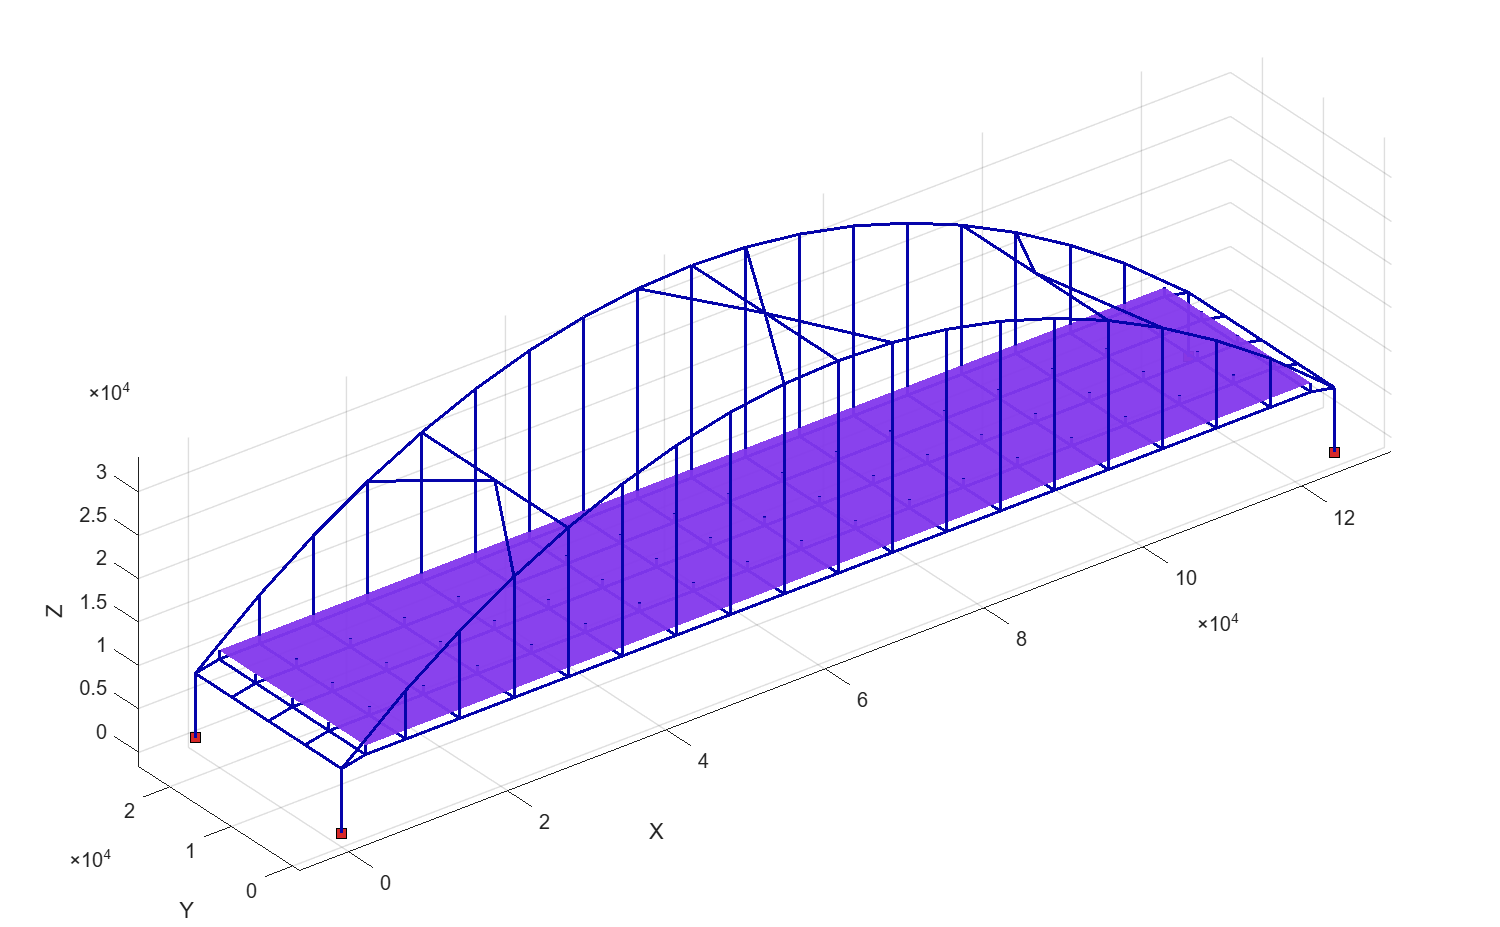

opsMAT.vis.plotModel();

We can retrieve data from the current model, which returns a nested `struct`. You can view the data using MATLAB's workspace variables.

modelData = opsMAT.post.getModelData();
disp(modelData)

           Nodes: [1×1 struct]
           Fixed: [1×1 struct]
    MPConstraint: [1×1 struct]
           Loads: [1×1 struct]
        Elements: [1×1 struct]
         NumNode: 241
      NumElement: 439



Finally, we can customize the control parameters for model visualization. Let's first take a look at the default parameter settings.

opts = opsMAT.vis.defaultPlotModelOptions;
% disp(opts)

Then

opts.nodes.show = true;
opts.nodes.size = 20;
opts.nodes.showLabels = true;

opsMAT.vis.plotModel(opts=opts);

[OpenSeesMatlab] Model summary
  Nodes: 241
  Beam elements: 367
  Shell elements: 72


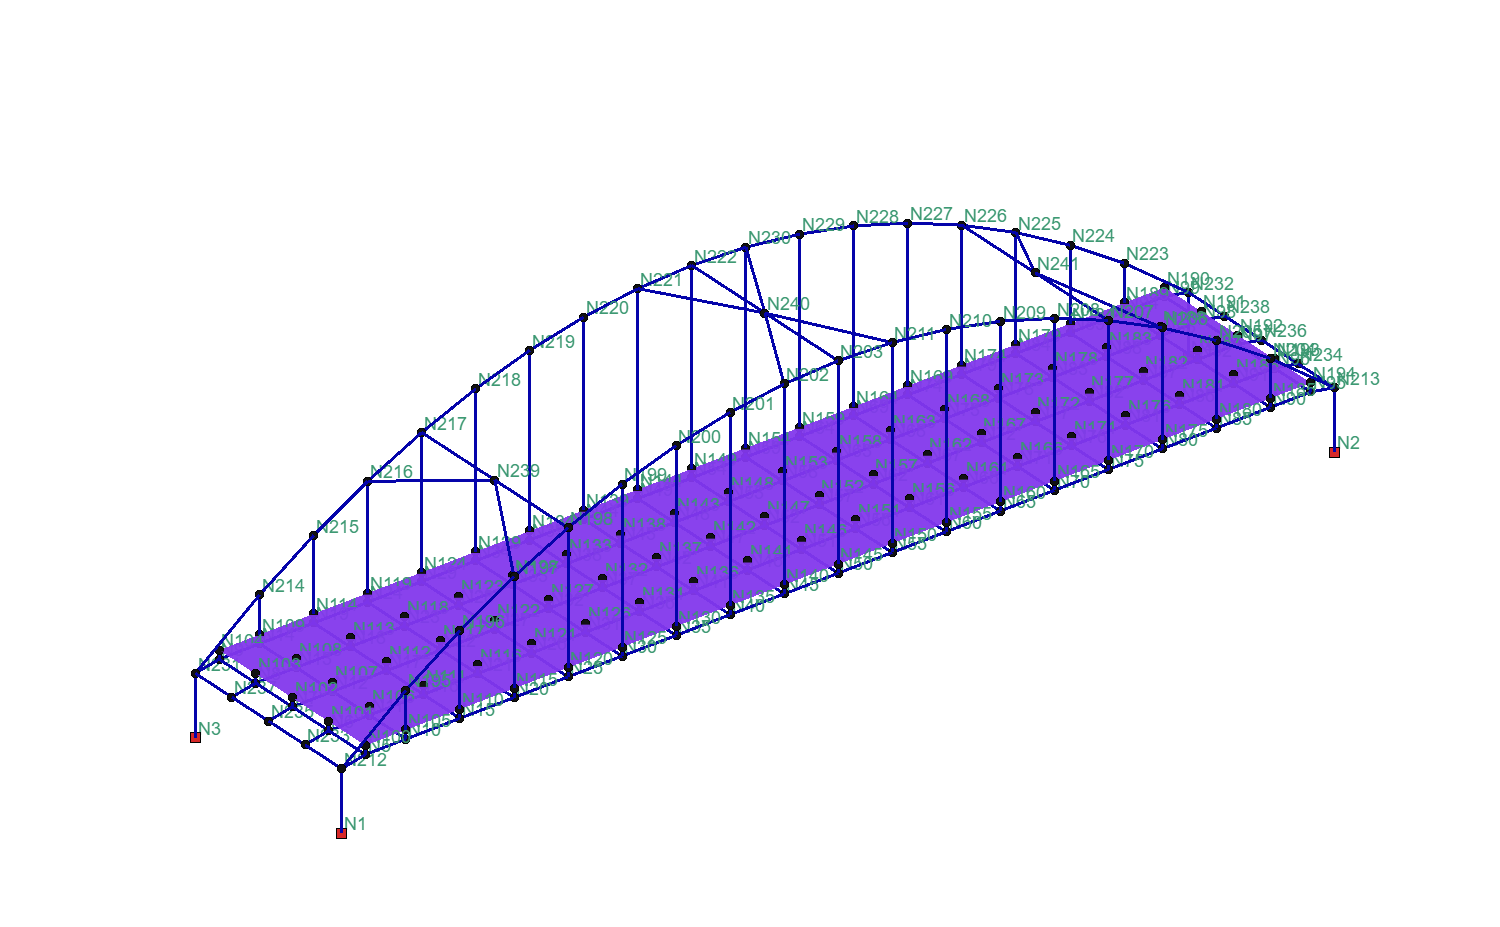

axis off

#### Visualization based on Matlab GUI

opsMAT.vis.plotModelGUI();

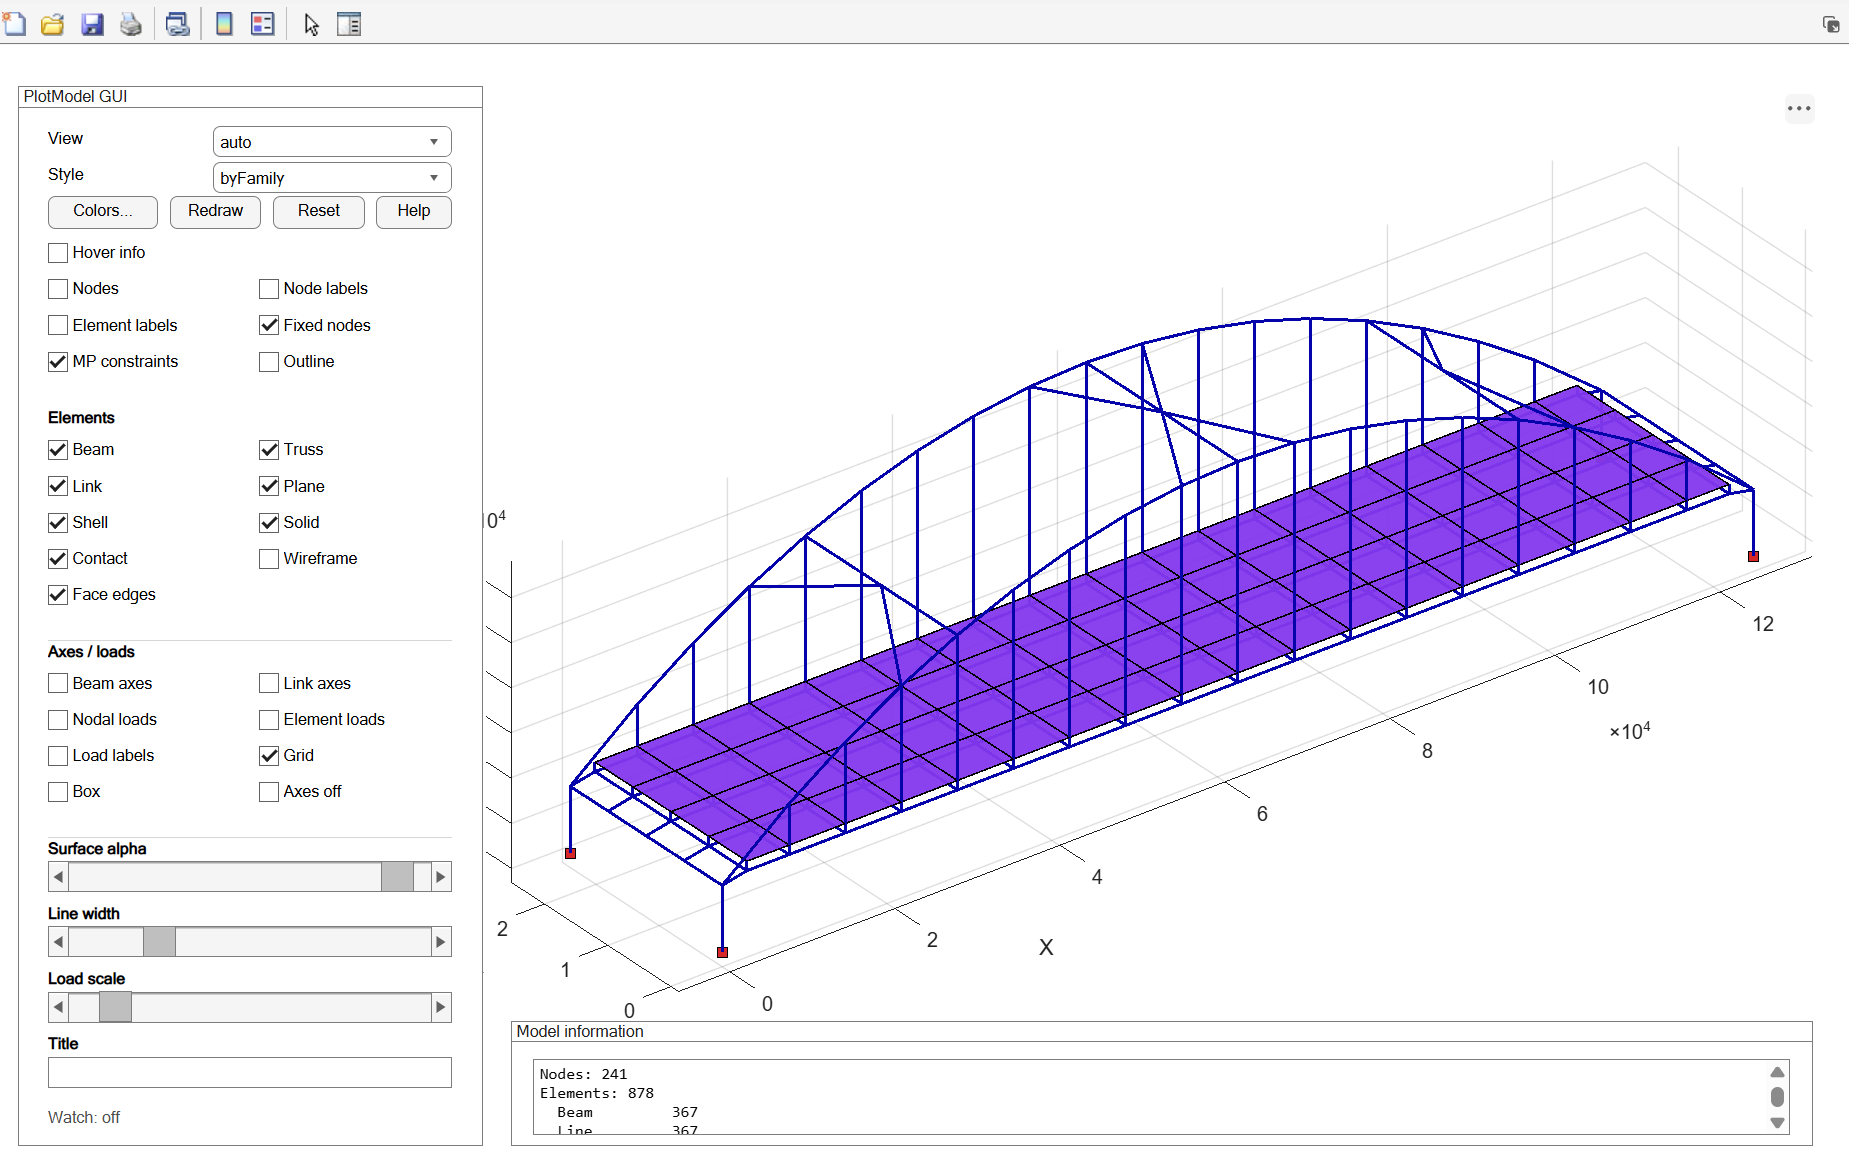

#### Visualization based on Polyscope GUI

opsMAT.vis.polyscope.plotModel();

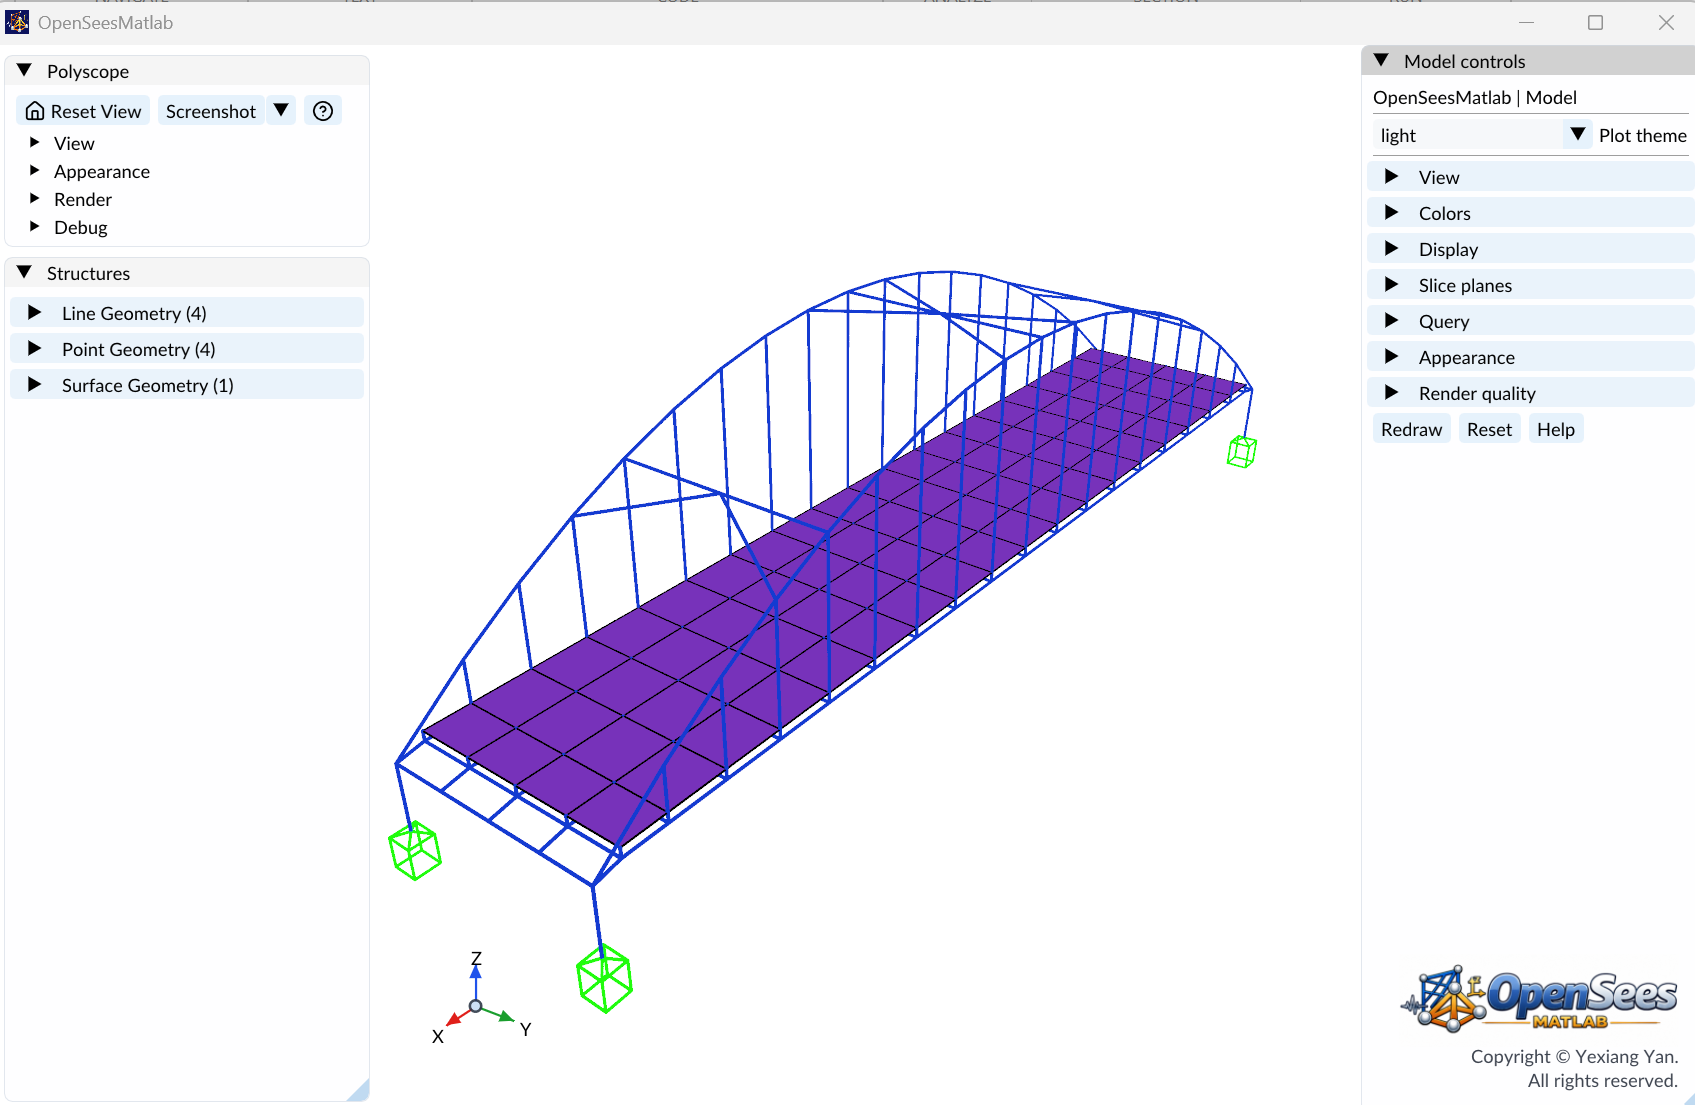

### Eigen visualization

First, we need to save the eigenvalue analysis results data for future reuse.

Then, data is retrieved from the file, returning a nested `structure` that stores the various results of the eigenvalue analysis.

tag = 1;
opsMAT.post.saveEigenData(tag, 10, solver='-genBandArpack');  % save

[OpenSees] Using DomainModalProperties - Developed by: Massimo Petracca, Guido Camata, ASDEA Software Technology


eigenData = opsMAT.post.getEigenData(odbTag=tag);  % get
disp(eigenData)

                EigenVectors: [1×1 struct]
    InterpolatedEigenVectors: [1×1 struct]
                  ModalProps: [1×1 struct]
                   ModelInfo: [1×1 struct]
                    ModeTags: [10×1 double]



Using this data, we can visualize the first modal shapes.

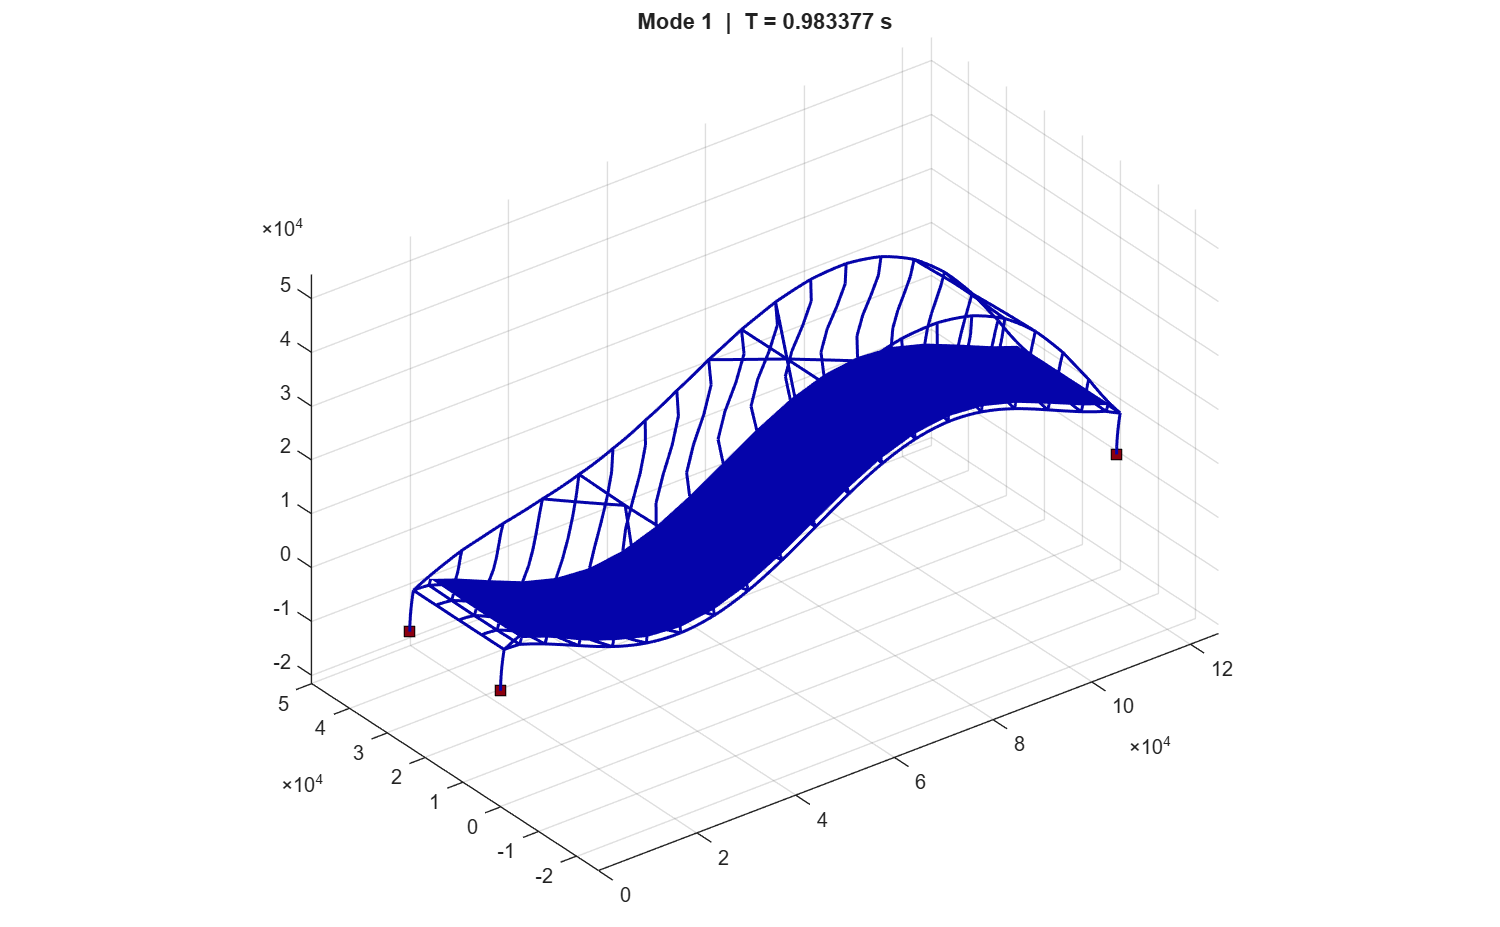

opsMAT.vis.plotEigen(1, eigenData);

and 5th

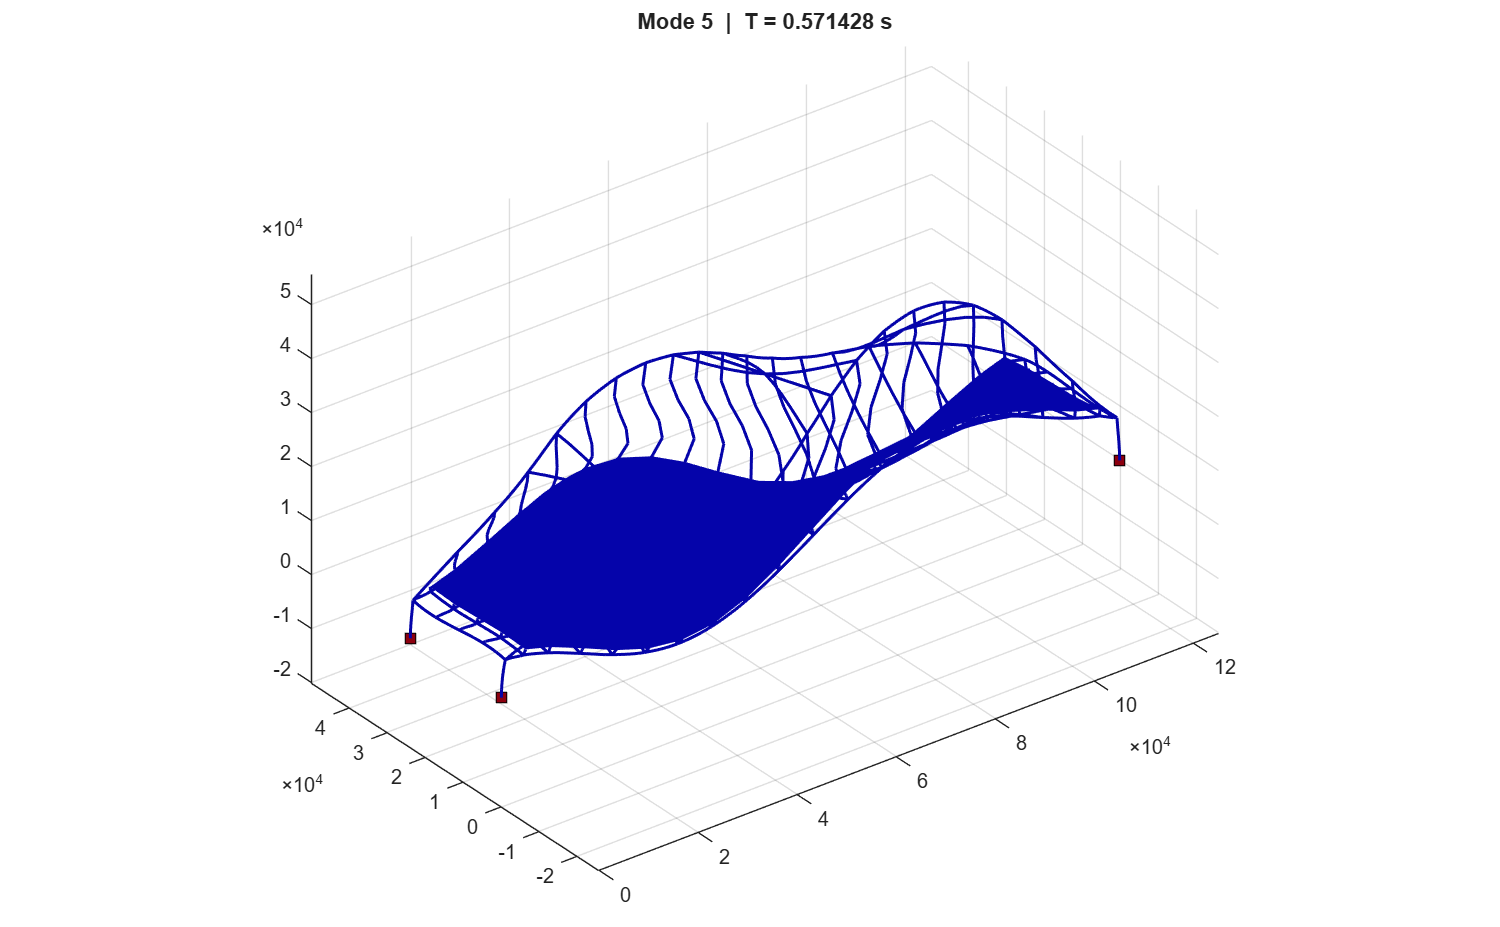

opsMAT.vis.plotEigen(5, eigenData);

Similarly, we obtain the default parameters.

opts = opsMAT.vis.defaultPlotEigenOptions;
% disp(opts.help)

For example:

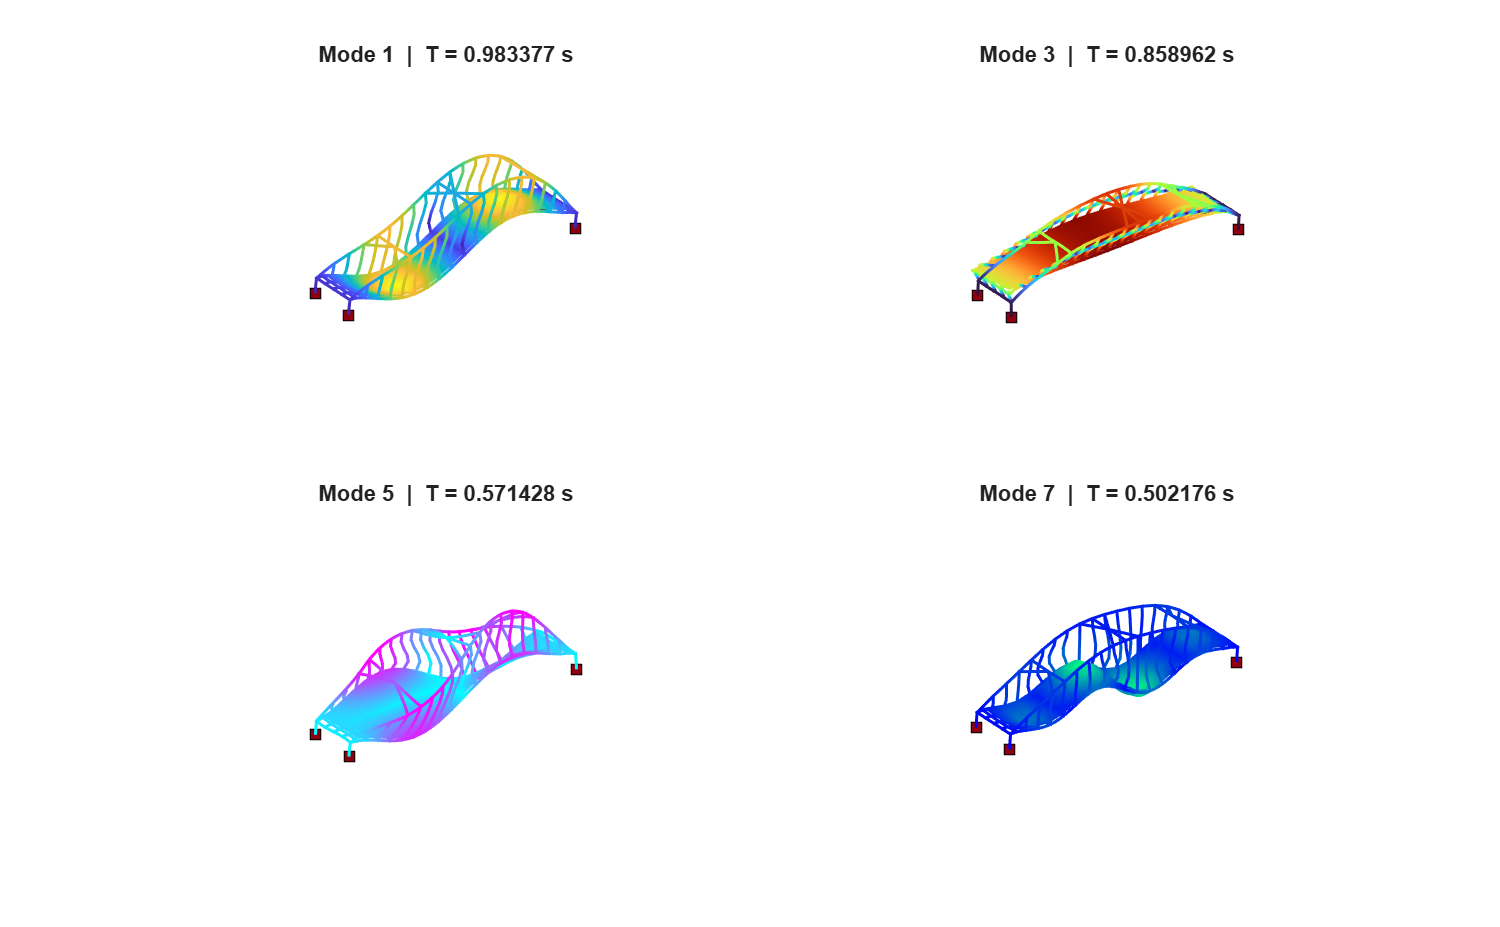

opts.color.useColormap = true;
% opts.color.colormap = jet(256);
modeTags = [1 3 5 7];
cmps = {"parula", "turbo", "cool", "winter"};

% Create a figure at position (100,100) with width=1200px and height=900px
figure('Position', [100, 100, 1200, 900]);
for i = 1:4
    subplot(2,2,i)
    ax = gca;
    opsMAT.vis.plotEigen(modeTags(i), eigenData, opts=opts, ax=ax);
    axis off;
    colormap(ax, cmps{i});
end

#### Visualization based on Matlab GUI

opsMAT.vis.plotEigenGUI(eigenData);

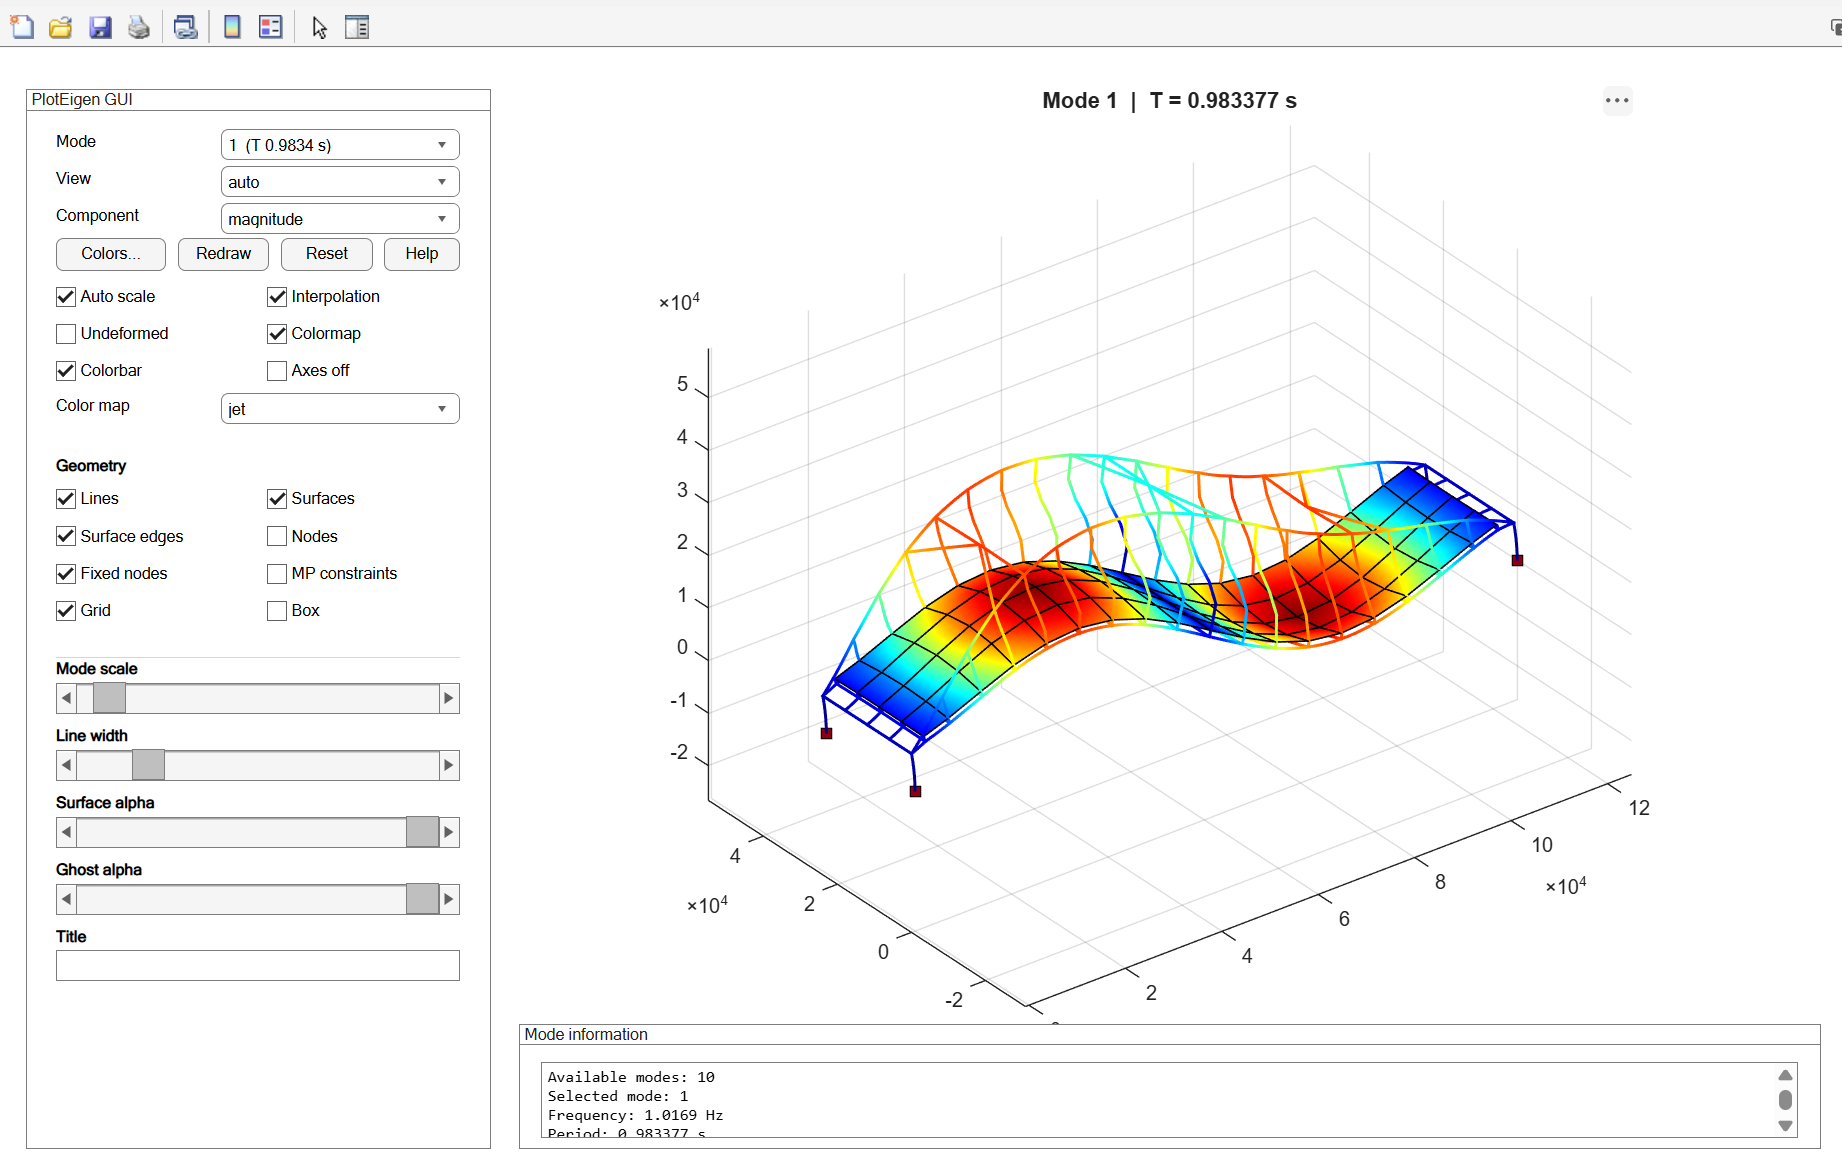

#### Visualization based on Polyscope GUI

opsMAT.vis.polyscope.plotEigen(eigenData);